myfolder = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/chemical/"

myfolder = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/chemical/"

filepattern_docu_table = fullfile(myfolder,"*.xlsx")

filepattern_docu_table = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/chemical/*.xlsx"

filepattern_supra = fullfile(myfolder,"*supra.txt")

filepattern_supra = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/chemical/*supra.txt"

filepattern_connectivity = fullfile(myfolder,"*connectivity.txt")

filepattern_connectivity = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/chemical/*connectivity.txt"


filelist_docu_table = dir(filepattern_docu_table);
filelist_connectivity = dir(filepattern_connectivity);

all_data_connect = struct

all_data_connect = struct with no fields.


for k = 1:length(filelist_docu_table)
    basefilename = filelist_docu_table(k).name;
    fullfilename = fullfile(filelist_docu_table(k).folder, basefilename);
    thisDocuTable = readtable(fullfilename, "VariableNamingRule", "preserve");
    all_data_connect(k).namen= basefilename;
    all_data_connect(k).docutables = thisDocuTable;
end

for k = 1:length(filelist_connectivity)
    basefilename = filelist_connectivity(k).name;
    fullfilename = fullfile(filelist_connectivity(k).folder, basefilename);
    thisConnectTable = readtable(fullfilename, "VariableNamingRule", "preserve");
    all_data_connect(k).namen_connect= basefilename;
    all_data_connect(k).connect = thisConnectTable;
end


# tSynapse


variable_names_types = [["synapse_ID", "string"]; ...
                        ["pre_syn", "string"]; ...
                        ["post_syn", "string"]; ...
                        ["is_connected", "double"]; ...
                        ["IPSP_stim_1", "double"]; ...
                        ["IPSP_stim_2", "double"]; ...
                        ["IPSP_stim_3", "double"]; ...
                        ["IPSP_stim_4", "double"]; ...
			            ["mean_IPSP", "double"];...
			            ["Synapse_Amplitude", "double"]];%add: prechannelID
			            %["Synapse_IPSP", "double"]]; %besser Ipsp o Epsp
% Make table using fieldnames & value types from above
tsnyapse = table('Size',[0,size(variable_names_types,1)],... 
	'VariableNames', variable_names_types(:,1),...
	'VariableTypes', variable_names_types(:,2));

id = 1

id = 1

for i=1:size(all_data_connect,2) %durch alle tables durch iterieren
    all_data_connect(i).tsynapse=tsnyapse;
    n=1;
    for channel_n = 1:10 %durch alle 10 channel iterieren
        
        if all_data_connect(i).docutables{channel_n,2} == 1
            S=strsplit(all_data_connect(i).namen_connect,"_");
            S=strjoin([S(2), S(3)],"_");
            cellIDpre = append(S,"_C", string(channel_n)); %je nachdem welcher Manipulator ==1, also included war;
            
            disp(cellIDpre);
            disp(channel_n);
            
        for channel_m = 1:10 %durch alle 10 channel iterieren
            if all_data_connect(i).docutables{channel_m,2} ==1
                S=strsplit(all_data_connect(i).namen_connect,"_");
                S=strjoin([S(2), S(3)],"_");
                cellIDpost = append(S,"_C", string(channel_m));%je nachdem welcher Manipulator ==1, also included war;
                disp(cellIDpost);
                disp(channel_m);
                if cellIDpre ~= cellIDpost %keine Connectivität bei C1=C1 
                all_data_connect(i).tsynapse(n,1)=array2table(id);
                all_data_connect(i).tsynapse(n,2)=array2table(cellIDpre);
                all_data_connect(i).tsynapse(n,3)=array2table(cellIDpost);
                jo = string(table2array(all_data_connect(i).docutables(channel_n,channel_m+2)));
                if jo=="1"
  
                colnames = all_data_connect(i).connect.Properties.VariableNames();

                for find_trace = 2:length(colnames)
                chan_name = strsplit(string(colnames(find_trace)), " ");
                chan_name=chan_name(2);
                if chan_name == string(channel_n)
                  presyn_trace=all_data_connect(i).connect(:,find_trace); %präsynapse 
                elseif chan_name == string(channel_m)
                  postsyn_trace=all_data_connect(i).connect(:,find_trace); %postsynapse
                end
                

                end
                all_data_connect(i).tsynapse(n,4)=array2table(1);

                end
                n=n+1 %Zähler für Spalten
                id = id + 1 %ID Zähler
                end 
            end
        end
        end
    
    end
end

20240819_002_C4


     4



20240819_002_C4


     4



20240819_002_C8


     8



n = 2

id = 2

20240819_002_C8


     8



20240819_002_C4


     4



n = 3

id = 3

20240819_002_C8


     8



20240821_000_C4


     4



20240821_000_C4


     4



20240821_000_C9


     9



n = 2

id = 4

20240821_000_C9


     9



20240821_000_C4


     4



n = 3

id = 5

20240821_000_C9


     9



20240821_002_C1


     1



20240821_002_C1


     1



20240821_002_C3


     3



n = 2

id = 6

20240821_002_C4


     4



n = 3

id = 7

20240821_002_C9


     9



n = 4

id = 8

20240821_002_C3


     3



20240821_002_C1


     1



n = 5

id = 9

20240821_002_C3


     3



20240821_002_C4


     4



n = 6

id = 10

20240821_002_C9


     9



n = 7

id = 11

20240821_002_C4


     4



20240821_002_C1


     1



n = 8

id = 12

20240821_002_C3


     3



n = 9

id = 13

20240821_002_C4


     4



20240821_002_C9


     9



n = 10

id = 14

20240821_002_C9


     9



20240821_002_C1


     1



n = 11

id = 15

20240821_002_C3


     3



n = 12

id = 16

20240821_002_C4


     4



n = 13

id = 17

20240821_002_C9


     9



20240821_004_C1


     1



20240821_004_C1


     1



20240821_004_C4


     4



n = 2

id = 18

20240821_004_C4


     4



20240821_004_C1


     1



n = 3

id = 19

20240821_004_C4


     4



20240822_000_C1


     1



20240822_000_C1


     1



20240822_000_C4


     4



n = 2

id = 20

20240822_000_C4


     4



20240822_000_C1


     1



n = 3

id = 21

20240822_000_C4


     4



20240822_002_C1


     1



20240822_002_C1


     1



20240822_002_C3


     3



n = 2

id = 22

20240822_002_C4


     4



n = 3

id = 23

20240822_002_C8


     8



n = 4

id = 24

20240822_002_C3


     3



20240822_002_C1


     1



n = 5

id = 25

20240822_002_C3


     3



20240822_002_C4


     4



n = 6

id = 26

20240822_002_C8


     8



n = 7

id = 27

20240822_002_C4


     4



20240822_002_C1


     1



n = 8

id = 28

20240822_002_C3


     3



n = 9

id = 29

20240822_002_C4


     4



20240822_002_C8


     8



n = 10

id = 30

20240822_002_C8


     8



20240822_002_C1


     1



n = 11

id = 31

20240822_002_C3


     3



n = 12

id = 32

20240822_002_C4


     4



n = 13

id = 33

20240822_002_C8


     8



20240822_005_C4


     4



20240822_005_C4


     4



20240822_005_C9


     9



n = 2

id = 34

20240822_005_C9


     9



20240822_005_C4


     4



n = 3

id = 35

20240822_005_C9


     9



20240823_000_C1


     1



20240823_000_C1


     1



20240823_000_C3


     3



n = 2

id = 36

20240823_000_C8


     8



n = 3

id = 37

20240823_000_C3


     3



20240823_000_C1


     1



n = 4

id = 38

20240823_000_C3


     3



20240823_000_C8


     8



n = 5

id = 39

20240823_000_C8


     8



20240823_000_C1


     1



n = 6

id = 40

20240823_000_C3


     3



n = 7

id = 41

20240823_000_C8


     8



20240823_002_C4


     4



20240823_002_C4


     4



20240823_002_C8


     8



n = 2

id = 42

20240823_002_C9


     9



n = 3

id = 43

20240823_002_C8


     8



20240823_002_C4


     4



n = 4

id = 44

20240823_002_C8


     8



20240823_002_C9


     9



n = 5

id = 45

20240823_002_C9


     9



20240823_002_C4


     4



n = 6

id = 46

20240823_002_C8


     8



n = 7

id = 47

20240823_002_C9


     9



20240823_004_C1


     1



20240823_004_C1


     1



20240823_004_C3


     3



n = 2

id = 48

20240823_004_C3


     3



20240823_004_C1


     1



n = 3

id = 49

20240823_004_C3


     3



20240826_006_C4


     4



20240826_006_C4


     4



20240826_006_C8


     8



n = 2

id = 50

20240826_006_C9


     9



n = 3

id = 51

20240826_006_C8


     8



20240826_006_C4


     4



n = 4

id = 52

20240826_006_C8


     8



20240826_006_C9


     9



n = 5

id = 53

20240826_006_C9


     9



20240826_006_C4


     4



n = 6

id = 54

20240826_006_C8


     8



n = 7

id = 55

20240826_006_C9


     9



20240826_007_C4


     4



20240826_007_C4


     4



20240826_007_C8


     8



n = 2

id = 56

20240826_007_C8


     8



20240826_007_C4


     4



n = 3

id = 57

20240826_007_C8


     8



20240826_011_C1


     1



20240826_011_C1


     1



20240826_011_C3


     3



n = 2

id = 58

20240826_011_C4


     4



n = 3

id = 59

20240826_011_C8


     8



n = 4

id = 60

20240826_011_C3


     3



20240826_011_C1


     1



n = 5

id = 61

20240826_011_C3


     3



20240826_011_C4


     4



n = 6

id = 62

20240826_011_C8


     8



n = 7

id = 63

20240826_011_C4


     4



20240826_011_C1


     1



n = 8

id = 64

20240826_011_C3


     3



n = 9

id = 65

20240826_011_C4


     4



20240826_011_C8


     8



n = 10

id = 66

20240826_011_C8


     8



20240826_011_C1


     1



n = 11

id = 67

20240826_011_C3


     3



n = 12

id = 68

20240826_011_C4


     4



n = 13

id = 69

20240826_011_C8


     8



20240827_002_C4


     4



20240827_002_C4


     4



20240827_002_C8


     8



n = 2

id = 70

20240827_002_C8


     8



20240827_002_C4


     4



n = 3

id = 71

20240827_002_C8


     8



20240827_004_C3


     3



20240827_004_C3


     3



20240827_004_C8


     8



n = 2

id = 72

20240827_004_C8


     8



20240827_004_C3


     3



n = 3

id = 73

20240827_004_C8


     8



20240827_007_C3


     3



20240827_007_C3


     3



20240827_007_C4


     4



n = 2

id = 74

20240827_007_C4


     4



20240827_007_C3


     3



n = 3

id = 75

20240827_007_C4


     4



20240829_000_C4


     4



20240829_000_C4


     4



20240829_000_C8


     8



n = 2

id = 76

20240829_000_C8


     8



20240829_000_C4


     4



n = 3

id = 77

20240829_000_C8


     8



20240829_002_C1


     1



20240829_002_C1


     1



20240829_002_C3


     3



n = 2

id = 78

20240829_002_C8


     8



n = 3

id = 79

20240829_002_C3


     3



20240829_002_C1


     1



n = 4

id = 80

20240829_002_C3


     3



20240829_002_C8


     8



n = 5

id = 81

20240829_002_C8


     8



20240829_002_C1


     1



n = 6

id = 82

20240829_002_C3


     3



n = 7

id = 83

20240829_002_C8


     8



20240829_004_C4


     4



20240829_004_C4


     4



20240829_004_C8


     8



n = 2

id = 84

20240829_004_C9


     9



n = 3

id = 85

20240829_004_C8


     8



20240829_004_C4


     4



n = 4

id = 86

20240829_004_C8


     8



20240829_004_C9


     9



n = 5

id = 87

20240829_004_C9


     9



20240829_004_C4


     4



n = 6

id = 88

20240829_004_C8


     8



n = 7

id = 89

20240829_004_C9


     9



20240902_002_C1


     1



20240902_002_C1


     1



20240902_002_C3


     3



n = 2

id = 90

20240902_002_C3


     3



20240902_002_C1


     1



n = 3

id = 91

20240902_002_C3


     3



20240903_004_C1


     1



20240903_004_C1


     1



20240903_004_C4


     4



n = 2

id = 92

20240903_004_C9


     9



n = 3

id = 93

20240903_004_C4


     4



20240903_004_C1


     1



n = 4

id = 94

20240903_004_C4


     4



20240903_004_C9


     9



n = 5

id = 95

20240903_004_C9


     9



20240903_004_C1


     1



n = 6

id = 96

20240903_004_C4


     4



n = 7

id = 97

20240903_004_C9


     9



20240903_008_C4


     4



20240903_008_C4


     4



20240903_008_C8


     8



n = 2

id = 98

20240903_008_C8


     8



20240903_008_C4


     4



n = 3

id = 99

20240903_008_C8


     8



20240910_000_C4


     4



20240910_000_C4


     4



20240910_000_C8


     8



n = 2

id = 100

20240910_000_C8


     8



20240910_000_C4


     4



n = 3

id = 101

20240910_000_C8


     8



20240910_002_C4


     4



20240910_002_C4


     4



20240910_002_C8


     8



n = 2

id = 102

20240910_002_C8


     8



20240910_002_C4


     4



n = 3

id = 103

20240910_002_C8


     8



20240911_000_C1


     1



20240911_000_C1


     1



20240911_000_C4


     4



n = 2

id = 104

20240911_000_C4


     4



20240911_000_C1


     1



n = 3

id = 105

20240911_000_C4


     4



20240911_002_C4


     4



20240911_002_C4


     4



20240911_002_C8


     8



n = 2

id = 106

20240911_002_C9


     9



n = 3

id = 107

20240911_002_C8


     8



20240911_002_C4


     4



n = 4

id = 108

20240911_002_C8


     8



20240911_002_C9


     9



n = 5

id = 109

20240911_002_C9


     9



20240911_002_C4


     4



n = 6

id = 110

20240911_002_C8


     8



n = 7

id = 111

20240911_002_C9


     9



20240911_006_C4


     4



20240911_006_C4


     4



20240911_006_C9


     9



n = 2

id = 112

20240911_006_C9


     9



20240911_006_C4


     4



n = 3

id = 113

20240911_006_C9


     9



20240911_008_C3


     3



20240911_008_C3


     3



20240911_008_C4


     4



n = 2

id = 114

20240911_008_C4


     4



20240911_008_C3


     3



n = 3

id = 115

20240911_008_C4


     4



    % colnames = all_data_connect(1).connect.Properties.VariableNames()
    % 
    % for find_trace = 2:length(colnames)
    % 
    %             chan_name = strsplit(string(colnames(find_trace)), " ")
    %             chan_name=chan_name(2)
    %             if chan_name == string(channel_n)
    %               presyn_trace=all_data_connect(1).connect(:,find_trace)  
    %             elseif chan_name == string(channel_m)
    %               postsyn_trace=all_data_connect(1).connect(:,find_trace)
    %             end
    %             %all_data_connect(i).tsynapse(n,4)=array2table(1)
    % 
    %             %postsyn_trace=all_data_connect(i).connect()
    % end 
    % 


                % diff_trace_segment = diff(table2array(presyn_trace));
                % diff_threshold = 2;
                % Stimulus_time = find(diff_trace_segment>diff_threshold, 1, "first")
                % plot(table2array(presyn_trace))
                % post_segment = (table2array(postsyn_trace))
                


% die Variable synapse zählt wie viele Synapsen in allen Experimenten verbunden sind
synapsen = 0 

synapsen = 0

% n_Synapse zählt die Synapsen die NICHT verbunden sind
n_synapse = 0

n_synapse = 0

% wie hoch ist die Wahrscheinl,ichkeit, dass eine Synapse gefunden wird, in
% dem jeweiligen Experiment
connectivity_per_exp = []


connectivity_per_exp =

     []



% loop geht durch alle Spalten von 1 bis zumletzten Eintrag 
for i = 1:length(all_data_connect)
    % zählen der Synapsen pro Experiment
    synapsen_y=0;
    % zählen der NICHT Synapsen pro Experiment
    synapsen_n=0;
    all_connect= all_data_connect(i).tsynapse.is_connected;
    for s = 1: length(all_connect)
    if all_connect(s) == 1
        synapsen = synapsen+1;
        synapsen_y= synapsen_y+1;
    else 
        n_synapse = n_synapse+1;
        synapsen_n= synapsen_n+1;
    end
    end
    prozent_pro_exp= synapsen_y/(synapsen_n+synapsen_y);
    connectivity_per_exp = [connectivity_per_exp,prozent_pro_exp];
    
end

synapsen

synapsen = 10

n_synapse

n_synapse = 104

prozent = synapsen/(n_synapse+synapsen)

prozent = 0.0877

connectivity_per_exp

connectivity_per_exp =          0         0    0.0833         0         0    0.3333         0    0.1667         0         0         0         0         0         0         0         0         0         0         0    0.5000         0    0.5000    0.5000         0         0    0.1667         0         0


mean(connectivity_per_exp)

ans = 0.0804

times = (0.1:1.5:13.6)*20000

times =         2000       32000       62000       92000      122000      152000      182000      212000      242000      272000


pre_syn_cell = 1

post_syn_cell = 3

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "1"


colname = "1"

colname = 1×2 string array
    "Manip."    "3"


colname = "3"

colname = 1×2 string array
    "Manip."    "4"


colname = "4"

colname = 1×2 string array
    "Manip."    "8"


colname = "8"

colname = 1×2 string array
    "Manip."    "9"


colname = "9"

min_first_stim = -59.5424

min_second_stim = -59.4217

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -59.4754

avg_max = -59.0353

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 0.7237

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/chemical/20240821_002_C1__20240821_002_C3widerview_chem_synapse_plot_rat.pdf"

pre_syn_cell = 3

post_syn_cell = 1

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "1"


colname = "1"

colname = 1×2 string array
    "Manip."    "3"


colname = "3"

colname = 1×2 string array
    "Manip."    "4"


colname = "4"

colname = 1×2 string array
    "Manip."    "8"


colname = "8"

min_first_stim = -48.2407

min_second_stim = -48.2356

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -48.2000

avg_max = -47.9673

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 0.7387

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/chemical/20240822_002_C3__20240822_002_C1widerview_chem_synapse_plot_rat.pdf"

pre_syn_cell = 3

post_syn_cell = 8

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "1"


colname = "1"

colname = 1×2 string array
    "Manip."    "3"


colname = "3"

colname = 1×2 string array
    "Manip."    "4"


colname = "4"

colname = 1×2 string array
    "Manip."    "8"


colname = "8"

min_first_stim = -60.7058

min_second_stim = -60.6321

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -60.7382

avg_max = -60.4989

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 0.5687

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/chemical/20240822_002_C3__20240822_002_C8widerview_chem_synapse_plot_rat.pdf"

pre_syn_cell = 8

post_syn_cell = 1

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "1"


colname = "1"

colname = 1×2 string array
    "Manip."    "3"


colname = "3"

colname = 1×2 string array
    "Manip."    "4"


colname = "4"

colname = 1×2 string array
    "Manip."    "8"


colname = "8"

min_first_stim = -48.0042

min_second_stim = -48.0512

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -48.0439

avg_max = -47.6821

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 0.7986

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/chemical/20240822_002_C8__20240822_002_C1widerview_chem_synapse_plot_rat.pdf"

pre_syn_cell = 8

post_syn_cell = 4

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "1"


colname = "1"

colname = 1×2 string array
    "Manip."    "3"


colname = "3"

colname = 1×2 string array
    "Manip."    "4"


colname = "4"

colname = 1×2 string array
    "Manip."    "8"


colname = "8"

min_first_stim = -59.5996

min_second_stim = -59.6733

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -59.6622

avg_max = -59.4190

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 1.3604

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/chemical/20240822_002_C8__20240822_002_C4widerview_chem_synapse_plot_rat.pdf"

pre_syn_cell = 1

post_syn_cell = 3

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "1"


colname = "1"

colname = 1×2 string array
    "Manip."    "3"


colname = "3"

colname = 1×2 string array
    "Manip."    "8"


colname = "8"

min_first_stim = -57.3914

min_second_stim = -56.5948

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -56.5880

avg_max = -54.6143

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 0.6182

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/chemical/20240823_000_C1__20240823_000_C3widerview_chem_synapse_plot_rat.pdf"

pre_syn_cell = 3

post_syn_cell = 1

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "1"


colname = "1"

colname = 1×2 string array
    "Manip."    "3"


colname = "3"

min_first_stim = -55.0099

min_second_stim = -55.0113

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -55.0205

avg_max = -54.7041

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 0.6500

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/chemical/20240902_002_C3__20240902_002_C1widerview_chem_synapse_plot_rat.pdf"

pre_syn_cell = 8

post_syn_cell = 4

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "4"


colname = "4"

colname = 1×2 string array
    "Manip."    "8"


colname = "8"

min_first_stim = -61.0864

min_second_stim = -61.0995

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -61.0850

avg_max = -60.9275

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 0.8065

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/chemical/20240903_008_C8__20240903_008_C4widerview_chem_synapse_plot_rat.pdf"

pre_syn_cell = 4

post_syn_cell = 8

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "4"


colname = "4"

colname = 1×2 string array
    "Manip."    "8"


colname = "8"

min_first_stim = -61.8841

min_second_stim = -62.0561

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -62.0686

avg_max = -61.7426

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 1.2570

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/chemical/20240910_000_C4__20240910_000_C8widerview_chem_synapse_plot_rat.pdf"

pre_syn_cell = 8

post_syn_cell = 4

colname = "s"

colname = "s"

colname = 1×2 string array
    "Manip."    "1"


colname = "1"

colname = 1×2 string array
    "Manip."    "4"


colname = "4"

colname = 1×2 string array
    "Manip."    "8"


colname = "8"

colname = 1×2 string array
    "Manip."    "9"


colname = "9"

min_first_stim = -59.4371

min_second_stim = -59.5010

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


avg_min = -59.4448

avg_max = -59.2083

all_data_connect = 1×28 struct array with fields:
    namen
    docutables
    namen_connect
    connect
    tsynapse


PPR = 0.7202

filename_PLOT = "/Users/emiliathoma/Desktop/synapse_plots_rat/chemical/20240911_002_C8__20240911_002_C4widerview_chem_synapse_plot_rat.pdf"

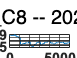

for j = 1:length(all_data_connect)
    for l = 1:height(all_data_connect(j).tsynapse)
        if all_data_connect(j).tsynapse.is_connected(l) == 1
            pre_syn_cell = strsplit(all_data_connect(j).tsynapse.pre_syn(l), "C");
            post_syn_cell = strsplit(all_data_connect(j).tsynapse.post_syn(l), "C");
            pre_syn_cell = double(pre_syn_cell(2))
            post_syn_cell = double(post_syn_cell(2))
            timestart= times(pre_syn_cell);
            properties = all_data_connect(j).connect.Properties.VariableNames;
            post_column=0;
            for entries = 1:length(properties)
                colname=(strsplit(string(properties(entries))," "))
                colname = colname(length(colname))
                if colname == string(post_syn_cell)
                      post_column = entries;
                end 
            end
            whole_stim = table2array(all_data_connect(j).connect(timestart-1000:(timestart+5000), post_column));
            first_stim = table2array(all_data_connect(j).connect(timestart:(timestart+1000), post_column));
            second_stim = table2array(all_data_connect(j).connect((timestart+1000):(timestart+2000), post_column));
            third_stim = table2array(all_data_connect(j).connect((timestart+2000):(timestart+3000), post_column));
            fourth_stim = table2array(all_data_connect(j).connect((timestart+3000):(timestart+4000), post_column));
            max_first_stim=max(first_stim);
            min_first_stim=min(first_stim)
            max_second_stim=max(second_stim);
            min_second_stim=min(second_stim)
            max_third_stim=max(third_stim);
            min_third_stim=min(third_stim);
            max_fourth_stim=max(fourth_stim);
            min_fourth_stim=min(fourth_stim);
            all_data_connect(j).tsynapse.IPSP_stim_1(l) = max_first_stim-min_first_stim
            all_data_connect(j).tsynapse.IPSP_stim_2(l) = max_second_stim-min_second_stim
            all_data_connect(j).tsynapse.IPSP_stim_3(l) = max_third_stim-min_third_stim
            all_data_connect(j).tsynapse.IPSP_stim_4(l) = max_fourth_stim-min_fourth_stim
            avg_min=mean([min_fourth_stim,min_third_stim,min_second_stim, min_first_stim])
            avg_max=mean([max_first_stim, max_fourth_stim, max_third_stim, max_second_stim])
            all_data_connect(j).tsynapse.mean_IPSP(l)= avg_max-avg_min
            
            PPR = all_data_connect(j).tsynapse.IPSP_stim_2(l)/all_data_connect(j).tsynapse.IPSP_stim_1(l)
            
                         clf

            
            subplot(3,1,[1:2])
             plot(whole_stim)
             yline(min_first_stim)
             yline(max_first_stim)
            % plot(second_stim)
             yline(min_second_stim)
             yline(max_second_stim)
            %             figure
            % plot(third_stim)
             yline(min_third_stim)
             yline(max_third_stim)
            %             figure
            % plot(fourth_stim)
             yline(min_fourth_stim)
             yline(max_fourth_stim)
             xline(1000)
             xline(2000)
             xline(3000)
             xline(4000)
             xline(5000)
             xlim([0 6000])
             
             sgtitle(strcat(char(all_data_connect(j).tsynapse.pre_syn(l))," -- ",string(all_data_connect(j).tsynapse.post_syn(l))), "Interpreter", "none")
            


            filename_PLOT =  strcat("/Users/emiliathoma/Desktop/synapse_plots_rat/chemical/",strcat(char(all_data_connect(j).tsynapse.pre_syn(l)),"__",string(all_data_connect(j).tsynapse.post_syn(l))),"widerview_chem_synapse_plot_rat.pdf")
            set(findobj(gcf,'type','axes'),'FontName','Arial','FontSize',8,'FontWeight','Bold', 'LineWidth', 1);
            set(gcf, "Units", "centimeters");
            screenposition = get(gcf, "Position");
            set(gcf, ...
                "PaperPosition",[0 0 22 34], ...
                "PaperSize", [22 33]) 

            print(gcf, filename_PLOT, "-dpdf", "-vector")
            


        end 
    end 
end 

timepoints= [0.1*2e4,3.1*2e4,4.6*2e4,10.6*2e4]

timepoints =         2000       62000       92000      212000


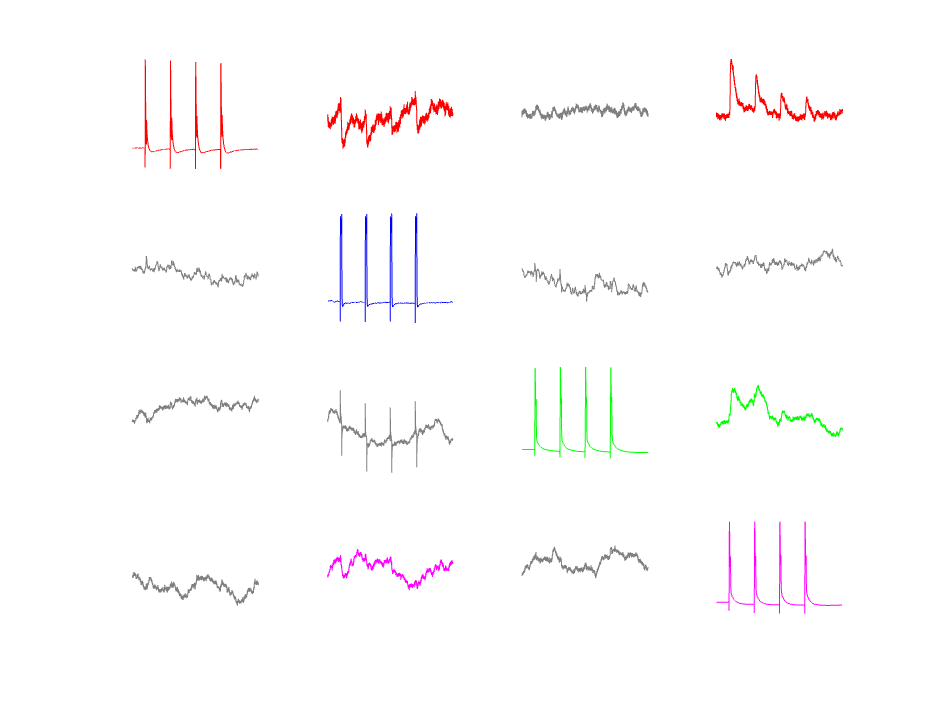


for i = 1:length(timepoints)
subplot(4,4,(0+i))
cell1=table2array(all_data_connect(6).connect(timepoints(i)-500:timepoints(i)+4500,2));
plot(cell1,"red")
if i == 3
plot(cell1, "Color" ,"#808080")
end
if i ~= 1
ylim([cell1(1)-0.5 cell1(1)+0.5])
end
if i == 2
ylim([cell1(1)-0.3 cell1(1)+0.3])
end

subplot(4,4,4+i)
cell2=table2array(all_data_connect(6).connect(timepoints(i)-500:timepoints(i)+4500,3));
plot(cell2, "Color" ,"#808080")
if i == 2
plot(cell2, "blue")
end
if i ~= 2
ylim([cell2(1)-2 cell2(1)+2])
end
subplot(4,4,8+i)
cell3=table2array(all_data_connect(6).connect(timepoints(i)-500:timepoints(i)+4500,4));
plot(cell3,"Color" ,"#808080")
if i == 3 | i == 4
plot(cell3, "green")
end
if i ~= 3
ylim([cell3(1)-0.5 cell3(1)+0.5])
end
subplot(4,4,12+i)
cell4=table2array(all_data_connect(6).connect(timepoints(i)-500:timepoints(i)+4500,5));
plot(cell4, "magenta")
if i == 1 || i == 3
plot(cell4, "Color" ,"#808080")
end
if i ~= 4
ylim([cell4(1)-0.5 cell4(1)+0.5])
end

end 



set(get(gcf, "Children"),"Visible", "off")

for s = 1:length(all_data_connect)
name = strsplit(all_data_connect(s).namen, "_docu_table.xlsx")
name = string(name(1))
writetable(all_data_connect(s).tsynapse,append("/Users/emiliathoma/Desktop/rat/chemical/", name,   "_chem_synapse_rat.csv") )










end

name = 1×2 cell array
    {'ET_20240819_002'}    {0×0 char}


name = "ET_20240819_002"

name = 1×2 cell array
    {'ET_20240821_000'}    {0×0 char}


name = "ET_20240821_000"

name = 1×2 cell array
    {'ET_20240821_002'}    {0×0 char}


name = "ET_20240821_002"

name = 1×2 cell array
    {'ET_20240821_004'}    {0×0 char}


name = "ET_20240821_004"

name = 1×2 cell array
    {'ET_20240822_000'}    {0×0 char}


name = "ET_20240822_000"

name = 1×2 cell array
    {'ET_20240822_002'}    {0×0 char}


name = "ET_20240822_002"

name = 1×2 cell array
    {'ET_20240822_005'}    {0×0 char}


name = "ET_20240822_005"

name = 1×2 cell array
    {'ET_20240823_000'}    {0×0 char}


name = "ET_20240823_000"

name = 1×2 cell array
    {'ET_20240823_002'}    {0×0 char}


name = "ET_20240823_002"

name = 1×2 cell array
    {'ET_20240823_004'}    {0×0 char}


name = "ET_20240823_004"

name = 1×2 cell array
    {'ET_20240826_006'}    {0×0 char}


name = "ET_20240826_006"

name = 1×2 cell array
    {'ET_20240826_007'}    {0×0 char}


name = "ET_20240826_007"

name = 1×2 cell array
    {'ET_20240826_011'}    {0×0 char}


name = "ET_20240826_011"

name = 1×2 cell array
    {'ET_20240827_002'}    {0×0 char}


name = "ET_20240827_002"

name = 1×2 cell array
    {'ET_20240827_004'}    {0×0 char}


name = "ET_20240827_004"

name = 1×2 cell array
    {'ET_20240827_007'}    {0×0 char}


name = "ET_20240827_007"

name = 1×2 cell array
    {'ET_20240829_000'}    {0×0 char}


name = "ET_20240829_000"

name = 1×2 cell array
    {'ET_20240829_002'}    {0×0 char}


name = "ET_20240829_002"

name = 1×2 cell array
    {'ET_20240829_004'}    {0×0 char}


name = "ET_20240829_004"

name = 1×2 cell array
    {'ET_20240902_002'}    {0×0 char}


name = "ET_20240902_002"

name = 1×2 cell array
    {'ET_20240903_004'}    {0×0 char}


name = "ET_20240903_004"

name = 1×2 cell array
    {'ET_20240903_008'}    {0×0 char}


name = "ET_20240903_008"

name = 1×2 cell array
    {'ET_20240910_000'}    {0×0 char}


name = "ET_20240910_000"

name = 1×2 cell array
    {'ET_20240910_002'}    {0×0 char}


name = "ET_20240910_002"

name = 1×2 cell array
    {'ET_20240911_000'}    {0×0 char}


name = "ET_20240911_000"

name = 1×2 cell array
    {'ET_20240911_002'}    {0×0 char}


name = "ET_20240911_002"

name = 1×2 cell array
    {'ET_20240911_006'}    {0×0 char}


name = "ET_20240911_006"

name = 1×2 cell array
    {'ET_20240911_008'}    {0×0 char}


name = "ET_20240911_008"